# Location Analysis

clear;
clc;
clf;

## Reference Population

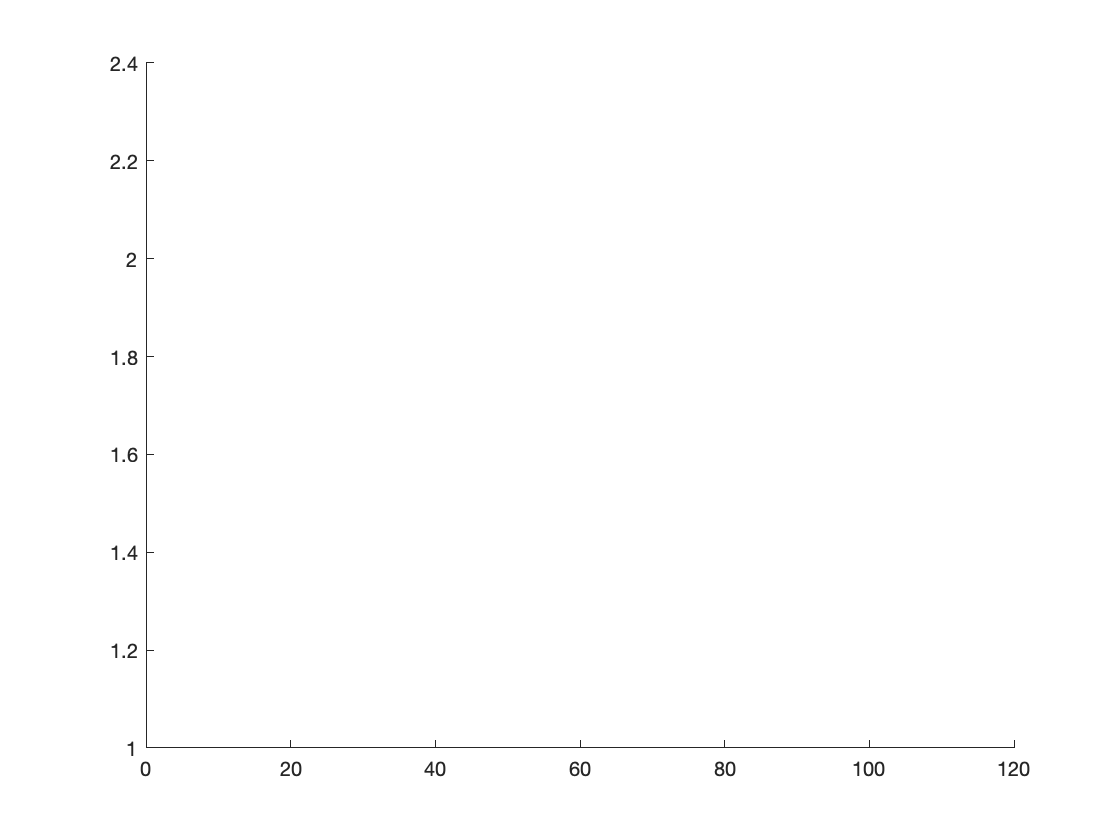

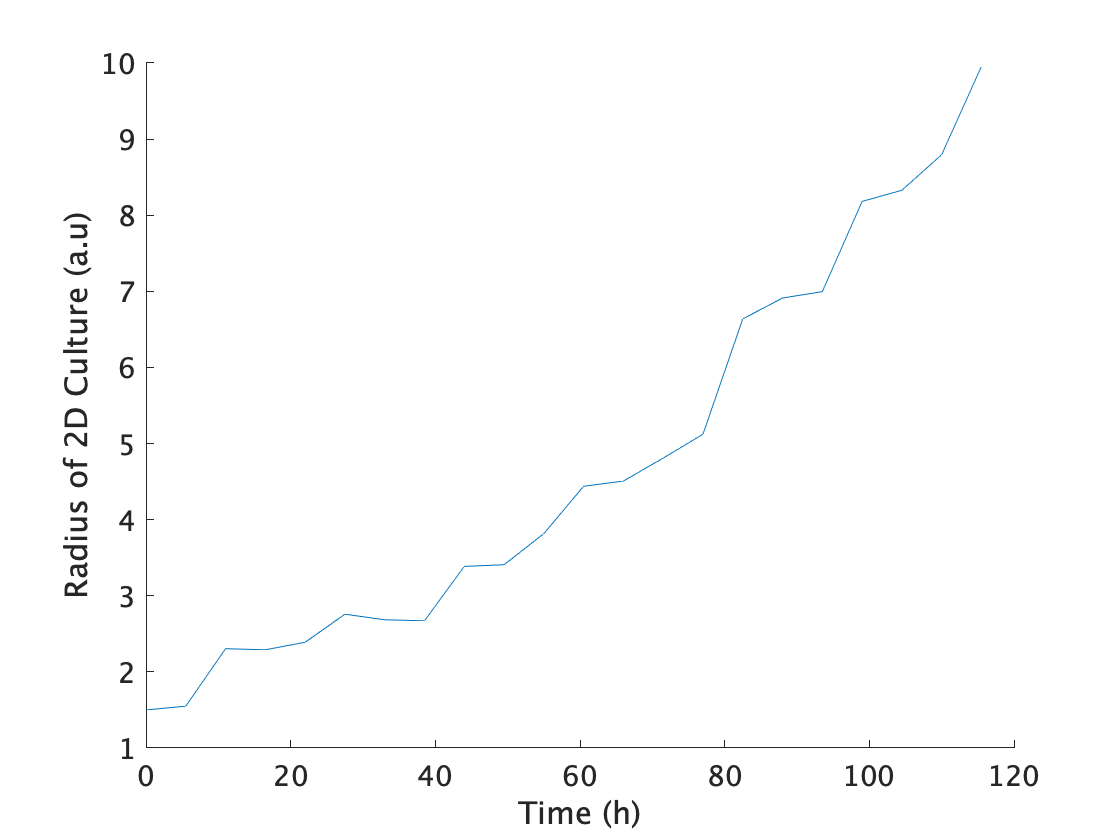

WT = "/Users/Priya/testoutput/TestMammaryMonolayer/2CellType/Control/n=1/results_from_time_0/location.dat";
[x,y] = TimeVsRadius(WT);

### n=1

RP_WT_1 = "/Users/Priya/testoutput/TestMammaryMonolayer/2CellType/Control/n=1/results_from_time_0/location.dat";
[RP_WT_1_x, RP_WT_1_y] = TimeVsRadius(RP_WT_1);

### n=2

RP_WT_2 = "/Users/Priya/testoutput/TestMammaryMonolayer/2CellType/Control/n=2/results_from_time_0/location.dat";
[RP_WT_2_x, RP_WT_2_y] = TimeVsRadius(RP_WT_2);

### n=3

RP_WT_3 = "/Users/Priya/testoutput/TestMammaryMonolayer/2CellType/Control/n=3/results_from_time_0/location.dat";
[RP_WT_3_x, RP_WT_3_y] = TimeVsRadius(RP_WT_3);

### n=4

RP_WT_4 = "/Users/Priya/testoutput/TestMammaryMonolayer/2CellType/Control/n=4/results_from_time_0/location.dat";
[RP_WT_4_x, RP_WT_4_y] = TimeVsRadius(RP_WT_4);

### n=5

RP_WT_5 = "/Users/Priya/testoutput/TestMammaryMonolayer/2CellType/Control/n=5/results_from_time_0/location.dat";
[RP_WT_5_x, RP_WT_5_y] = TimeVsRadius(RP_WT_5);

% combine data tables from all experiments into one table

yTotal_RP_WT = cat(2,RP_WT_1_x,RP_WT_2_x,RP_WT_3_x,RP_WT_4_x,RP_WT_5_x);

% transpose data table
time = x.';
yTotal_RP_WT_ = yTotal_RP_WT.';

% plot data with error bars
clf

hold on; 

RP_WTtotal = shadedErrorBar(time(:,1:55:end),yTotal_RP_WT_(:,1:55:end),{@mean,@std},'lineProps','k','transparent',0);

hold off;

ylabel ("Radius of 2D culture (a.u)")
xlabel('Time (hr)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";

folder = '~/Desktop/';
exportgraphics(gca, 'FigureRadiusof2DCulture.tiff');
movefile('FigureRadiusof2DCulture.tiff', folder);

## Reference Population with Stem Cells

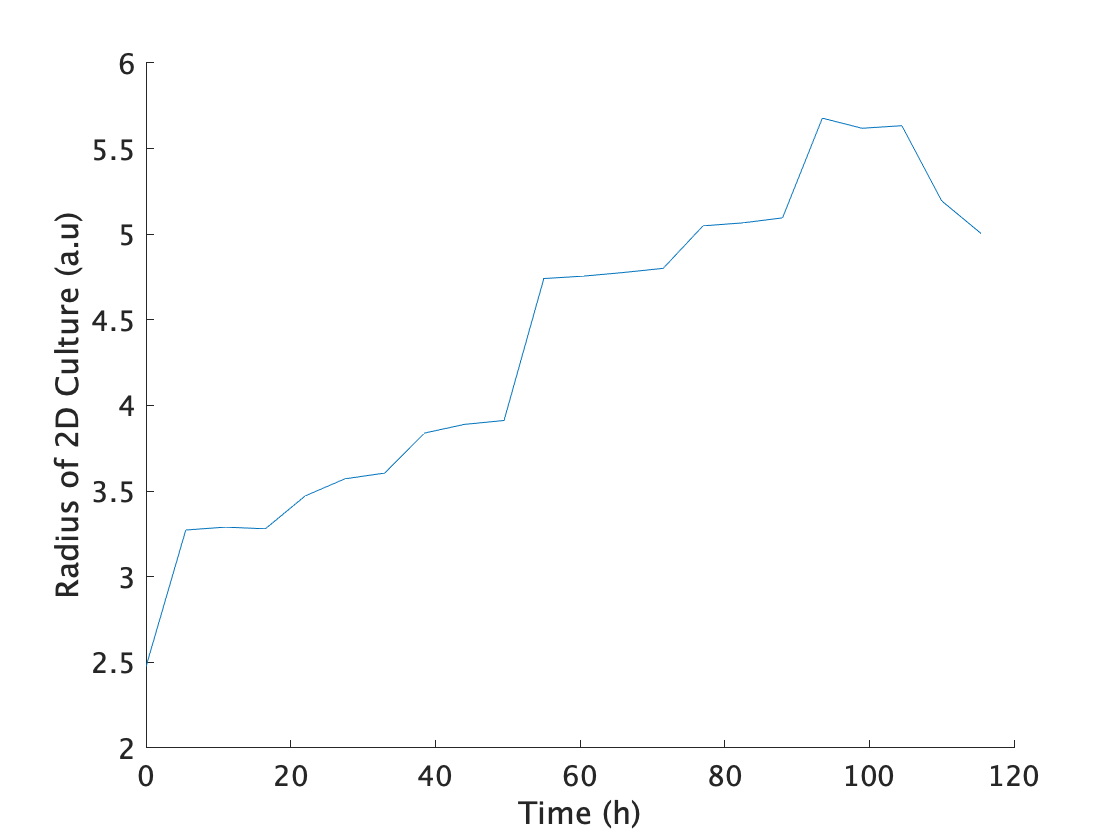

WT = "/Users/Priya/testoutput/TestMammaryMonolayer/StemCells/Control/WT/n=1/results_from_time_0/location.dat";
[x,y] = TimeVsRadius(WT);

### n=1

SC_WT_1 = "/Users/Priya/testoutput/TestMammaryMonolayer/StemCells/Control/WT/n=1/results_from_time_0/location.dat";
[x, SC_WT_1_y] = TimeVsRadius(SC_WT_1);

### n=2

SC_WT_2 = "/Users/Priya/testoutput/TestMammaryMonolayer/StemCells/Control/WT/n=2/results_from_time_0/location.dat";
[x, SC_WT_2_y] = TimeVsRadius(SC_WT_2);

### n=3

SC_WT_3 = "/Users/Priya/testoutput/TestMammaryMonolayer/StemCells/Control/WT/n=3/results_from_time_0/location.dat";
[x, SC_WT_3_y] = TimeVsRadius(SC_WT_3);

### n=4

SC_WT_4 = "/Users/Priya/testoutput/TestMammaryMonolayer/StemCells/Control/WT/n=4/results_from_time_0/location.dat";
[x, SC_WT_4_y] = TimeVsRadius(SC_WT_4);

### n=5

SC_WT_5 = "/Users/Priya/testoutput/TestMammaryMonolayer/StemCells/Control/WT/n=5/results_from_time_0/location.dat";
[x, SC_WT_5_y] = TimeVsRadius(SC_WT_5);

% combine data tables from all experiments into one table

yTotal_SC_WT = cat(2,SC_WT_1_y,SC_WT_2_y,SC_WT_3_y,SC_WT_4_y,SC_WT_5_y);

% transpose data table
time = x.';
yTotal_SC_WT_ = yTotal_SC_WT.';

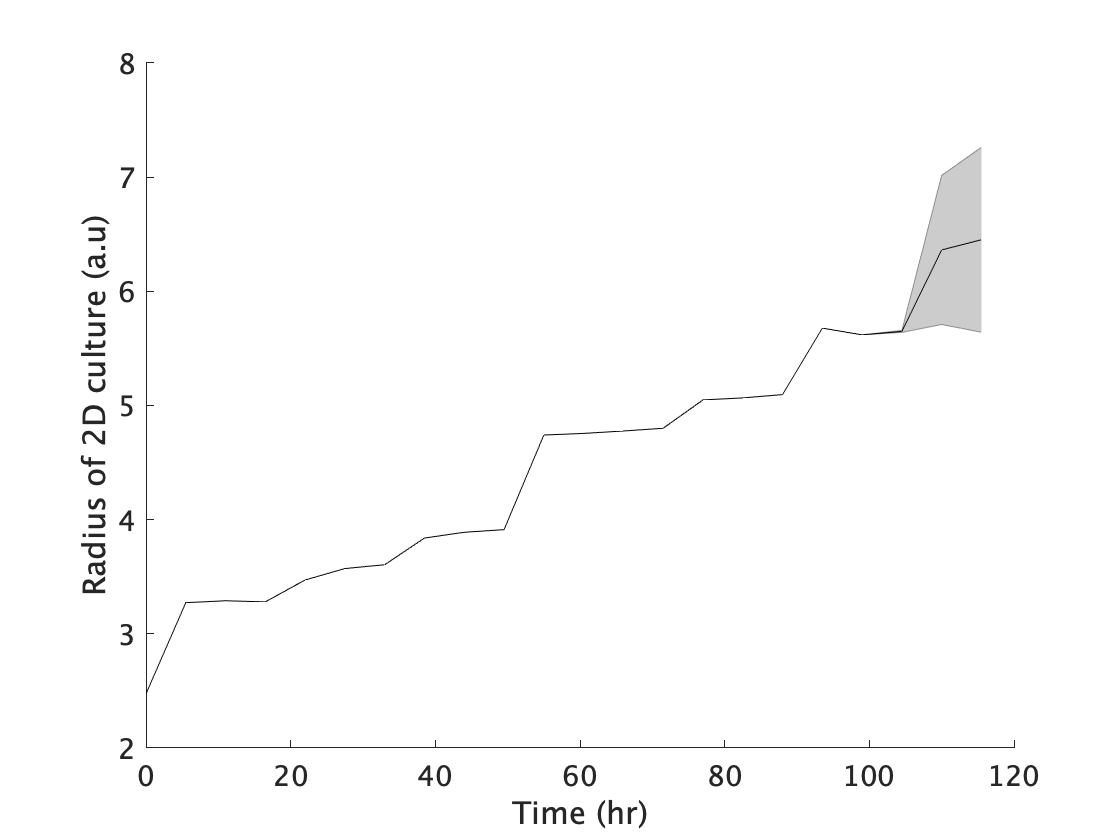

% plot data with error bars
clf

hold on; 

SC_WTtotal = shadedErrorBar(time(:,1:55:end),yTotal_SC_WT_(:,1:55:end),{@mean,@std},'lineProps','k','transparent',0);

hold off;

ylabel ("Radius of 2D culture (a.u)")
xlabel('Time (hr)')

ax = gca;
ax.FontSize = 14; 
ax.FontName = "Calibri";

folder = '~/Desktop/';
exportgraphics(gca, 'FigureRadiusof2DCulture.tiff');

movefile('FigureRadiusof2DCulture.tiff', folder);